# Influence of the dataset size on the godness of fit

The generalized SEIR model should be handled with precaution when it comes to prediction. The present example illustrates how bad can be the prediction if the data set is too small. The Case of Hunan (China) is used in the following. 

## Load the data from the database

clearvars;close all;clc;
% Download the data from ref [1] and read them with the function getDataCOVID
[tableConfirmed,tableDeaths,tableRecovered,time] = getDataCOVID();
% time = time(1:end-1);
fprintf(['Most recent update: ',datestr(time(end)),'\n'])

Most recent update: 04-Apr-2020




Location = 'Hunan';


try
    indR = find(contains(tableRecovered.ProvinceState,Location)==1)
    indC = find(contains(tableConfirmed.ProvinceState,Location)==1)
    indD = find(contains(tableDeaths.ProvinceState,Location)==1)
catch exception
    searchLoc = strfind(tableRecovered.ProvinceState,Location)
    indR = find([searchLoc{:}]==1)
    
    searchLoc = strfind(tableConfirmed.ProvinceState,Location)
    indC = find([searchLoc{:}]==1)
    
    searchLoc = strfind(tableConfirmed.ProvinceState,Location)
    indD = find([searchLoc{:}]==1)
    
    
end

indR = 56

indC = 65

indD = 65


tableRecovered(indR,1:2)

ans = 1×2 table
    ProvinceState    CountryRegion
    _____________    _____________

       "Hunan"          "China"   


indR = indR(1)

indR = 56



Recovered = table2array(tableRecovered(indR,5:end));
Deaths = table2array(tableDeaths(indD,5:end));
Confirmed = table2array(tableConfirmed(indC,5:end));
% If the number of confirmed Confirmed cases is small, it is difficult to know whether
% the quarantine has been rigorously applied or not. In addition, this
% suggests that the number of infectious is much larger than the number of
% confirmed cases
minNum= 20;
Recovered(Confirmed<=minNum)=[];
Deaths(Confirmed<=minNum)=[];
time(Confirmed<=minNum)= [];
Confirmed(Confirmed<=minNum)=[];

if isempty(Confirmed)
    warning('"Confirmed" is an empty array. Check the value of "minNum". Computation aborted.')
    return
end


disp(tableConfirmed(indC,1:2))

    ProvinceState    CountryRegion
    _____________    _____________

       "Hunan"          "China"   



indC = indC(1);
Npop = 67.37e6; % Population

## Initial conditions


% Definition of the first estimates for the parameters
alpha_guess = 0.06; % protection rate
beta_guess = 1.0; % Infection rate
LT_guess = 5; % latent time in days
QT_guess = 21; % quarantine time in days
lambda_guess = [0.1,0.05]; % recovery rate
kappa_guess = [0.1,0.05]; % death rate

% guess is used for the fitting
guess = [alpha_guess,...
    beta_guess,...
    1/LT_guess,...
    1/QT_guess,...
    lambda_guess,...
    kappa_guess];

E0 = Confirmed(1); % Initial number of exposed cases. Unknown but unlikely to be zero.
I0 = Confirmed(1); % Initial number of infectious cases. Unknown but unlikely to be zero.
Q0 = Confirmed(1);
R0 = Recovered(1);
D0 = Deaths(1);

% For simulation purpose
Ndays = numel(time); % total number of days available
dt = 0.1; % time step
time1 = datetime(time(1)):dt:datetime(time(1)+datenum(Ndays-1));
N = numel(time1);
t = [0:N-1].*dt;
maxDay = 25; % maximal number of days of data used for the fitting
milestones = [3:1:maxDay,Ndays]; % Milestone days used for fittings: fir from first to 7th day, 8th, etc 
Nframes = numel(milestones);
Q = nan(Nframes,N); % preallocated fitted cases of quarantined cases

## Visualization as a gif

The code used to create a gif is taken from the Matlab submision by Chad Greene: [https://se.mathworks.com/matlabcentral/fileexchange/63239-gif](https://se.mathworks.com/matlabcentral/fileexchange/63239-gif)

I did not include the function gif.m into the submission but you can download it from the above link.

clf;close all;
fig = figure;

#### First frame

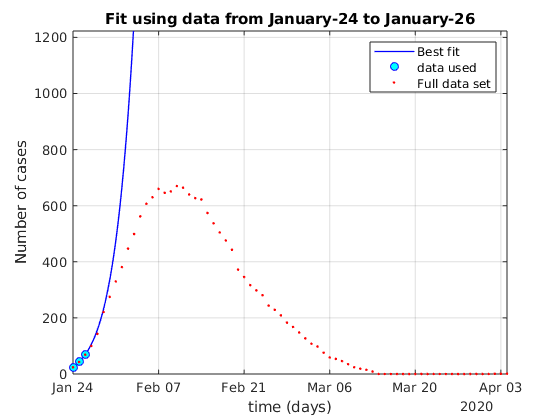

ii=milestones(1); % first frame

[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = ...
    fit_SEIQRDP(Confirmed(1:ii)-Recovered(1:ii)-Deaths(1:ii),Recovered(1:ii),Deaths(1:ii),Npop,E0,I0,time(1:ii),guess,'Display','off');

[~,~,~,Q(1,:),~,~,~] = ...
    SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t);

plot1 = plot(time1,Q(1,:),'b','linewidth',1);
hold on
box on
plot2 = plot(time(1:ii),Confirmed(1:ii)-Recovered(1:ii)-Deaths(1:ii),'bo','markerfacecolor','c');
plot3 = plot(time,Confirmed-Recovered-Deaths,'r.');

ylabel('Number of cases')
xlabel('time (days)')
leg = {'Best fit','data used','Full data set'};
legend([plot1,plot2, plot3],leg{:},'location','northeast')
set(fig,'color','w')
grid on
ylim([0, 1.2*max(Confirmed)]);
xlim([time(1), time(end)]);
title(['Fit using data from ',datestr(time(1),'mmmm-dd'),...
    ' to ',datestr(time(ii),'mmmm-dd')])

#### Other frames

gif('uncertainties.gif','DelayTime',1,'LoopCount',inf,'frame',gcf)


ll=1;
for ii=milestones(2:end)
    % Least-square fit to the data
    Q1 = Confirmed(1:ii)-Recovered(1:ii)-Deaths(1:ii);
    R1 = Recovered(1:ii);
    D1 = Deaths(1:ii);
    timeData = time(1:ii);
    [alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = ...
        fit_SEIQRDP(Q1,R1,D1,Npop,E0,I0,timeData,guess,'Display','off');
    % Compute the fitted response
    [~,~,~,Q(ll,:),~,~,~] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t);
    ll=ll+1;
end

#### Plot the frames

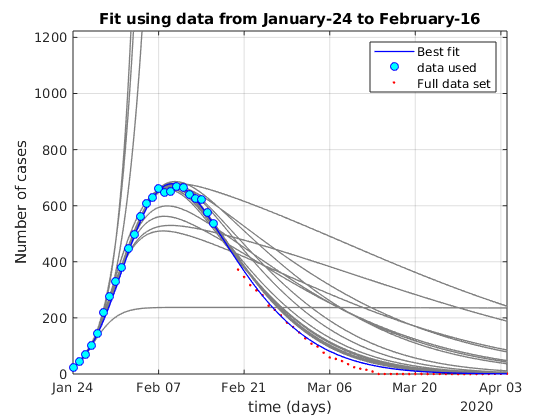

ll=1;
plot1.Color = 'b';
for jj = 2:Nframes
    plot1.Color = [0.5,0.5,0.5];
    plot1 = plot(time1,Q(ll,:),'b','linewidth',1);
    plot1.Color = [0 0 1];
    set(plot2,'Xdata',time(1:jj),'Ydata',Confirmed(1:jj)-Recovered(1:jj)-Deaths(1:jj))
    uistack(plot2,'top')
    title(['Fit using data from ',datestr(time(1),'mmmm-dd'),' to ',datestr(time(jj),'mmmm-dd')])
    legend([plot1,plot2, plot3],leg{:},'location','northeast')
    ylim([0, 1.2*max(Confirmed)]);
    xlim([time(1), time(end)]);
    ll=ll+1;
    gif
end

#### Animate the gif